addpath("C:\Users\jackh\OneDrive\MATLAB\aeroelasticity_research\onera-m6\import_data")
warning('off','all')

figure;
AoA = [2 4 6]

AoA =      2     4     6


M = [0.70 0.75 0.80 0.85 0.90 0.95 1.00 1.10 1.20]

M =     0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.1000    1.2000



colorscale = 0.8

colorscale = 0.8000

colorbank = {[128, 0, 255]*colorscale/256 [0, 32, 255]*colorscale/256 [0, 128, 255]*colorscale/256 [0, 255, 255]*colorscale/256 [0, 255, 0]*colorscale/256 [255, 191, 0]*colorscale/256 [255, 128, 0]*colorscale/256 [255, 0, 0]*colorscale/256 [255, 0, 191]*colorscale/256};
markerbank = {'o' '^' 'd'};
markersize = 2; markerindices = 5:10:1000; markerfacecolor = 'w'; linewidth = 1.0;

AeroData = cell(length(AoA),length(M));
LiftLines = gobjects(size(AeroData));
DragLines = gobjects(size(AeroData));
LegendLabels = string(size(AeroData));






for ind_AoA=1:length(AoA)

    figure('Renderer', 'painters', 'Position', [10 10 1000 500]);
    T = tiledlayout(1,2);
    T.XLabel.String = "$$\textup{Time} \ \textup{[s]}$$";
    T.XLabel.Interpreter = 'latex';
    T.TileSpacing = 'compact';
    T.Title.String = "$$\textup{Transient Lift and Drag Coeffients: }\alpha=\ $$"+AoA(ind_AoA)+"$$^{\circ} \ \textup{(Rigid)}$$";
    T.Title.Interpreter = 'latex';

    ax1 = nexttile;
    ax1.FontName = 'Times';
    ax1.Box = 'on';
    ax1.XAxis.TickLabelFormat = '%.3f';
    ax1.XAxis.Limits = [0,0.100];
    ax1.YAxis.Label.String = "$$C_{L,rigid}$$";
    ax1.YAxis.Label.Interpreter = 'latex';

    for ind_M=1:length(M)
        AeroData{ind_AoA,ind_M} = importAeroDataRigid(AoA(ind_AoA), M(ind_M));
        LiftLines(ind_AoA,ind_M) = line(AeroData{ind_AoA,ind_M}.Time, AeroData{ind_AoA,ind_M}.LiftCoef);
        LiftLines(ind_AoA,ind_M).Marker = markerbank{ind_AoA};
        LiftLines(ind_AoA,ind_M).MarkerSize = markersize;
        LiftLines(ind_AoA,ind_M).MarkerIndices = markerindices;
        LiftLines(ind_AoA,ind_M).MarkerFaceColor = markerfacecolor;
        LiftLines(ind_AoA,ind_M).LineWidth = linewidth;
        LiftLines(ind_AoA,ind_M).Color = colorbank{ind_M};
        LiftLines(ind_AoA,ind_M).MarkerEdgeColor = colorbank{ind_M};
        LiftLines(ind_AoA,ind_M).LineStyle = '-';
        LegendLabels(ind_AoA,ind_M) = "C_L: \alpha=" + AeroData{ind_AoA,ind_M}.AoA + "°, M=" + AeroData{ind_AoA,ind_M}.MachNumber;
    end
    legend(LegendLabels(ind_AoA,:), Location="southoutside",FontSize=6,NumColumns=3)


    ax2 = nexttile;
    ax2.FontName = 'Times';
    ax2.Box = 'on';
    ax2.XAxis.TickLabelFormat = '%.3f';
    ax2.XAxis.Limits = [0,0.100];
    ax2.YAxis.Label.String = "$$C_{D,rigid}$$";
    ax2.YAxis.Label.Interpreter = 'latex';


    for ind_M=1:length(M)
        AeroData{ind_AoA,ind_M} = importAeroDataRigid(AoA(ind_AoA), M(ind_M));
        DragLines(ind_AoA,ind_M) = line(AeroData{ind_AoA,ind_M}.Time, AeroData{ind_AoA,ind_M}.DragCoef);
        DragLines(ind_AoA,ind_M).Marker = markerbank{ind_AoA};
        DragLines(ind_AoA,ind_M).MarkerSize = markersize;
        DragLines(ind_AoA,ind_M).MarkerIndices = markerindices;
        DragLines(ind_AoA,ind_M).MarkerFaceColor = markerfacecolor;
        DragLines(ind_AoA,ind_M).LineWidth = linewidth;
        DragLines(ind_AoA,ind_M).Color = colorbank{ind_M};
        DragLines(ind_AoA,ind_M).MarkerEdgeColor = colorbank{ind_M};
        DragLines(ind_AoA,ind_M).LineStyle = '-';
        LegendLabels(ind_AoA,ind_M) = "C_D: \alpha=" + AeroData{ind_AoA,ind_M}.AoA + "°, M=" + AeroData{ind_AoA,ind_M}.MachNumber;
    end
    legend(LegendLabels(ind_AoA,:), Location="southoutside",FontSize=6,NumColumns=3)



filenamestring="C:\Users\jackh\OneDrive\MATLAB\aeroelasticity_research\onera-m6\plot_aero_data\graphs_rigid\Rigid-Aero-Coefs-Graph-" + num2str(AoA(ind_AoA)) + "deg.png"

filenamestring = "C:\Users\jackh\OneDrive\MATLAB\aeroelasticity_research\onera-m6\plot_aero_data\graphs_rigid\Rigid-Aero-Coefs-Graph-2deg.png"

filenamestring = "C:\Users\jackh\OneDrive\MATLAB\aeroelasticity_research\onera-m6\plot_aero_data\graphs_rigid\Rigid-Aero-Coefs-Graph-4deg.png"

filenamestring = "C:\Users\jackh\OneDrive\MATLAB\aeroelasticity_research\onera-m6\plot_aero_data\graphs_rigid\Rigid-Aero-Coefs-Graph-6deg.png"

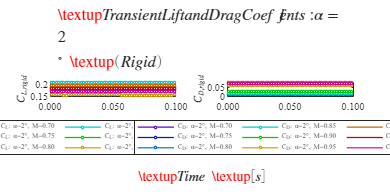

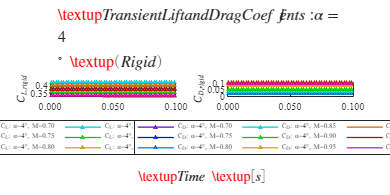

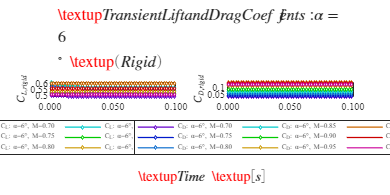

exportgraphics(gcf,filenamestring,"Resolution",600,"BackgroundColor","none",ContentType="vector")

end